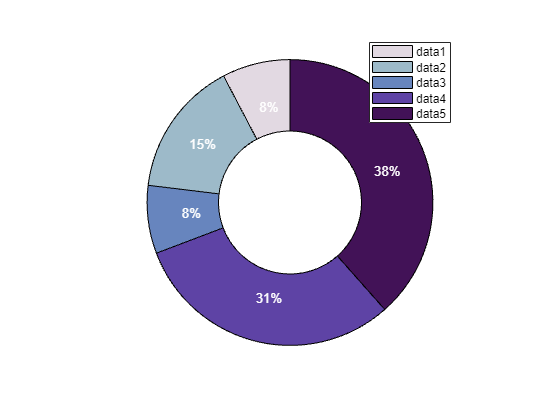

% circularPieDemo 
X=[1,2,1,4,5];
pieHdl=pie(X);
hold on
% 颜色列表，修改颜色和标签位置
colorList=[0.8858    0.8500    0.8880
    0.6173    0.7311    0.7864
    0.4041    0.5218    0.7440
    0.3668    0.2640    0.6465
    0.2589    0.0720    0.3397];
for i=2:2:length(pieHdl)
    pieHdl(i).Position=pieHdl(i).Position.*.57;
    pieHdl(i).Color=[1,1,1];
    pieHdl(i-1).FaceColor=colorList(i/2,:);
end
legend('AutoUpdate','off')
% 画个圆
t=linspace(0,2*pi,200);
fill(cos(t).*.5,sin(t).*.5,'w')